# Atividade 07_05

Otávio Baziewicz Filho - 1942808

clc; clear; close all; 

## Detecção de bordas usando o método Canny (função edge)

Teste o detector de bordas Canny (ver https://www.mathworks.com/help/images/ref/edge.html) para diferentes valores dos limiares T_low e T_high.

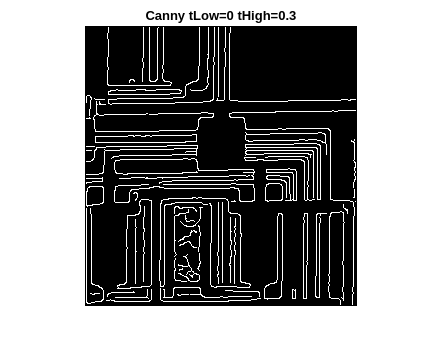

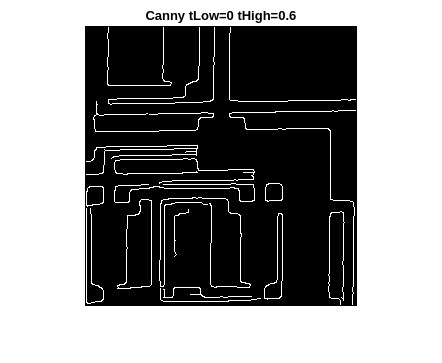

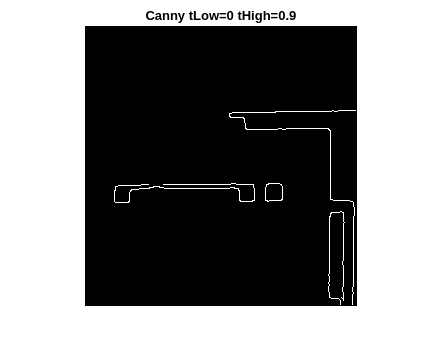

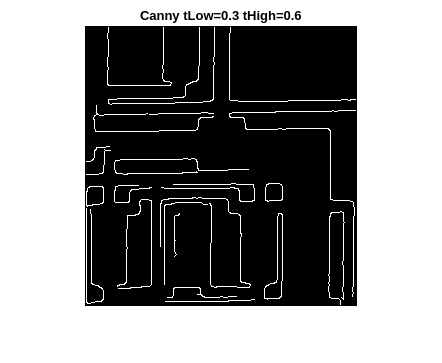

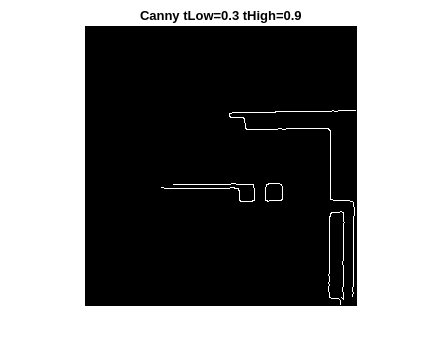

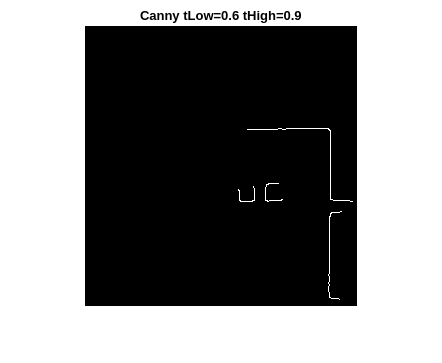

img = imread("circuit.tif");

tLowArray = 0:0.3:0.9;
tHighArray = 0:0.3:0.9;


for tLow = tLowArray
    for tHigh = tHighArray
        if (tLow < tHigh)
            canny = edge(img, "canny", [tLow, tHigh]);

            figure, imshow(canny)
            title("Canny tLow=" + tLow + " tHigh=" + tHigh)
        end
    end
end